# Analyze specific experiments using linear (background) digging model and no background (scale factor) model

use 'dAdtModel2.m' function: [MdAdt,Am] = dAdtModel2(ta,tb,m,b,dPdt,A0)

for both models use: ta = -51 and tb = 0

for scale factor model use m=2.175 and b=0.

**Need new way to evaluate model prediction for between modeled and real dAdt**

because correlation in independent of scale factor, need something in addition. RMSE doesn't cancel out positive and negative errors so not useful. RMSE for final result is problematic as it can vary greatly only due to few misses in dAdt modeling.

Use R-squared instead of correlation coefficient, to get proportion of explained variance.

**USE MAE (mean absolute error) instead of RMSE.**

**TRY: **percent of data points in modeled Area with absolute error less than the MAE + 1 SD == ACCURACY

which is 3.9346 cm^2/day. Round up to 4.

*For mean tArea get ****87.23%***

# Get R-squared and %Accurate for all use nests

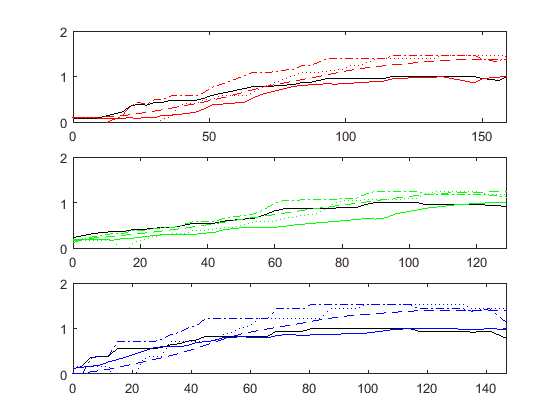

UseNests = [3:8 11:13 15:18 20 22 23 25:29];
%% Get pop and A data per nest k
load('Data\MeanData\fArea_Pop_All_S.mat','PopBin','t')
load('Data\MeanData\tArea_All_S.mat','tAbin')


figure
colors = [1 0 0;0 1 0;0 0 1];
EvalTable = table;
Ks = [3 4 25];
for i=1:numel(Ks)
    k = Ks(i);
    t0 = find(t==0)-1;
    tend = find(~isnan(tAbin(:,k)),1,'last');
    time = t(t0:tend);
    tA = tAbin(t0:tend,k);
    dAdt = diff(tA)./3;
    dAdt(dAdt<0) = 0; % filter out negative digging rates, and replace them as 0
    pop = PopBin(t0:tend,k);
    dPdt = diff(pop)./3;
    
    [MdAdt,Am] = dAdtModel2(-51,0,2.175,0,dPdt,tA(1));
    
    EvalTable.tag(i) = k;%{['F',num2str(k)]};
    
    EvalTable.NoB_Rsq(i) = 1-(sum((dAdt-MdAdt).^2)/numel(dAdt))/var(dAdt,1);
    AbsE1 = abs(tA-Am);
    EvalTable.NoB_MAE(i) = mean(AbsE1);
    EvalTable.NoB_Accuracy(i) = sum(AbsE1<=4)/numel(AbsE1);
   
%     figure
%     subplot(1,2,1)
%     plot(time(1:end-1),dAdt,'-s',time(1:end-1),MdAdt)
%     xlabel('time')
%     ylabel('dAdt')
%     %title({[EvalTable.tag{i},': No Bkgrnd Model Rsq = ',num2str(round(EvalTable.NoB_Rsq(i),2))];...
%       %  ['Bkgrnd Model Rsq = ',num2str(round(EvalTable.B_Rsq(i),2))]})
%     
%     subplot(1,2,2)
%     plot(time,tA,'-s',time,Am)
%     xlabel('time')
%     ylabel('tArea')
%     %legend({'Results','No Bkgrnd','Bkgrnd'},'Location','southoutside')
%     title([': No Bkgrnd Accuracy = ',num2str(100.*round(EvalTable.NoB_Accuracy(i),3)),'%'])

% use linear fit model to predict density-dependent model
Am2 = predict(lm,pop);
% try lag time linear model
idx_w5 = find(pop>=5,1);
Am3 = repmat(tA(idx_w5),numel(tA),1);
Am3(idx_w5:end) = predict(lm,pop(1:end-idx_w5+1));

subplot(3,1,i)
%plot(time,pop./max(pop),'-k')
hold on
plot(time,tA./max(tA),'-','Color',colors(i,:))
plot(time,Am./max(tA),'--','Color',colors(i,:))
%plot(time,Am2./max(tA),'-.','Color',colors(i,:))
plot(time,Am3./max(tA),':','Color',colors(i,:))
xlim([0 max(time)])
ylim([0 2])
end

Mean accuracy

Mean_NoB_accu = mean(EvalTable.NoB_Accuracy)

Mean_NoB_accu = 0.0521

Mean_NoB_MAE = mean(EvalTable.NoB_MAE)

Mean_NoB_MAE = 46.7138

**Conclusion: Use no-background digging model, due to higher accuracy.**

**However general low accuracy overall.**

**Need to think of all different reasons for change in area, digging rate is only one contributer.**